%Fecha de actualización: 21/septiembre/2023
clc
clear all

**UNIVERSIDAD NACIONAL AUTÓNOMA DE MÉXICO**

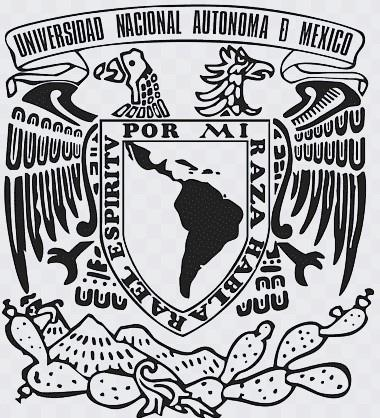

**FACULTAD DE INGENIERÍA**

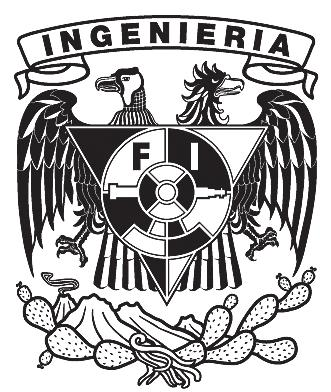

**PROFESOR:** 		     Luis Antonio Aguilar Pérez

**SEMESTRE:** 		     2024-1

**GRUPO:** 			     02

**TAREA:** 			     Ejercicios DataStore en Matlab

**ALUMNA:** 		     Margarita Méndez Aguilar

**FECHA ENTREGA:**     27 Septiembre 2023

# Manipulación de archivos de datos

Un modelo de datos o DataFrame es una estructura de datos tabular, la cual organiza la información en filas y columnas de manera similar a una hoja de cálculo. En particular cada columna del DataFrame representa una variable o feature (atributo), mientras que cada fila representa una observación o registro realizado. Los DataFrames son utilizados comúnmente en análisis de datos para manipular y analizar grandes conjuntos de datos de forma eficiente. Existen diversos métodos de almacenar esta informacion dependiendo del lenguaje de programacion utilizado. El formato universal y más tradicional de almacenamiento de la informacion es mediante archivos de tipo CSV. Un archivo de formato CSV es en realidad un archivo en formato de codificacion de texto plano, donde cada línea del archivo representa una fila de datos, y los valores de cada columna están separados por un carácter delimitador, siendo generalmente este una coma. Es un formato popular debido a su simplicidad y fácil manipulación por programas y hojas de cálculo. Además, muchos sistemas y aplicaciones pueden exportar datos en formato CSV, lo que lo hace fácilmente intercambiable entre diferentes plataformas y herramientas. En particular un archivo de tipo CSV se visualiza de la siguiente manera:

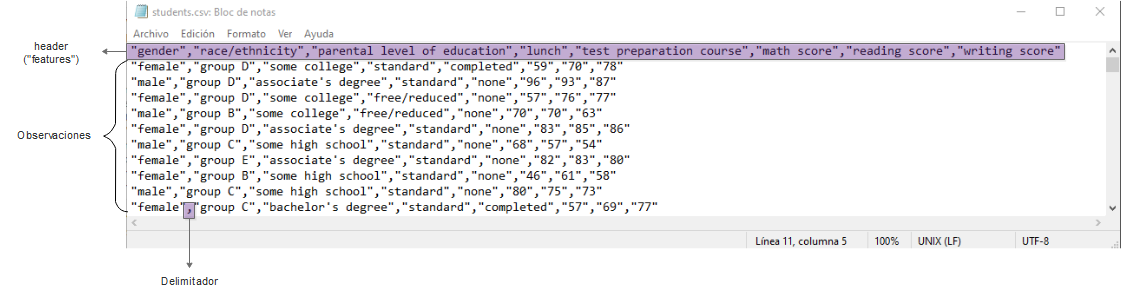

**Figura 1.-** Archivo de tipo CSV visualizado como texto plano

Existen otros formatos de archivos como el parquet, el cual es un formato de archivo de almacenamiento de datos de código abierto utilizado para almacenar datos tabulares en una estructura de columna, en lugar de una estructura de fila tradicional. Este formato está diseñado para ser eficiente en términos de almacenamiento y procesamiento, y permite una lectura y escritura más rápida de grandes conjuntos de datos. En particular, al estar los datos encriptados y codificados en este tipo de archivos, no es posible visualizarlos de manera tradicional, aunque el esquema de organizacion de la información seria lo más cercano a este:

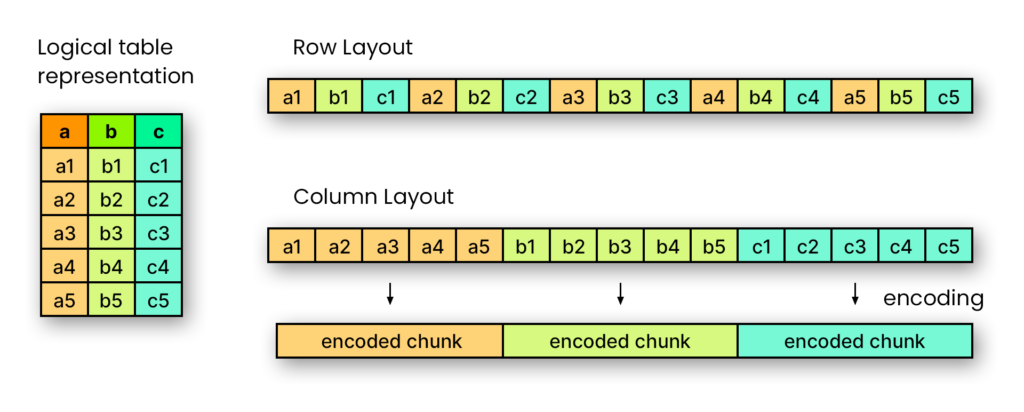

**Figura 2.-** Esquema tradicional de codificacion tipo parquet

Finalmente, el uso y manejo de modelos de datos en MATLAB se realiza mediante la funcion "Datastore". Esta es una función que proporciona una interfaz rápida para acceder a grandes conjuntos de datos, como archivos de imágenes, archivos de audio o archivos de texto, sin cargarlos en la memoria. Permite la lectura de datos de manera eficiente y escalable, ya que lee y procesa los datos de forma incremental a medida que se necesitan, lo que permite trabajar con grandes conjuntos de datos sin tener que cargarlos por completo en la memoria. Además, la función "datastore" permite realizar operaciones de preprocesamiento y manipulación de datos, como filtrado y transformación de datos, de manera eficiente y fácil. Estas bases de datos tienen la siguiente estructura de informacion 

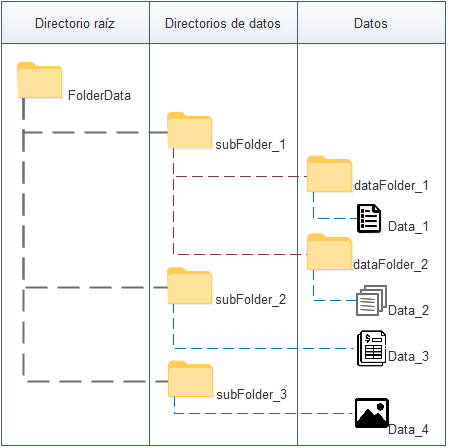

**Figura 3.-** Esquema de un modelo de datos

### --- Pasos iniciales

%%%
%Creacion de directorio de trabajo
%rootFolder = 'D:\TSISB_IA';
rootFolder ='C:\Users\Maggie\Documents\MATLAB\TSISB_IA';
workingFolder = 'tareaejercicio_1';
tempFolder = 'temp';
savePath = fullfile(rootFolder,workingFolder);
saveTempPath = fullfile(rootFolder,workingFolder,tempFolder);

prefix = ['\' 'students'];
sufix = '.csv';
newName = [prefix, sufix];

%Despues de correr esta celda una vez, crea un bloque de comentarios a partir de esta linea

if ~exist(savePath,'dir')
    [status, message, ~] = mkdir(savePath);
    if status == 0
        disp(message)
    end
end

if ~exist(saveTempPath,'dir')
    [status, message, ~] = mkdir(saveTempPath);
    if status == 0
        disp(message)
    end
end

%%%
%Organizacion y copia de archivos
[fileName, pathFileName] = uigetfile('C:\','*.txt' );

if isequal(fileName,0)
    disp('Se canceló la busqueda de archivos');
else
    disp(['El usuario seleccionó el archivo ', fullfile(pathFileName,fileName)]);
    [status, message, ~] = copyfile([pathFileName,fileName],[saveTempPath,newName]);
    if status == 0
        disp(message)
    else
        disp(['El cual se movio a la dirección ', fullfile(saveTempPath)]);
    end
end

El usuario seleccionó el archivo C:\Users\Maggie\Downloads\students.csv


El cual se movio a la dirección C:\Users\Maggie\Documents\MATLAB\TSISB_IA\tareaejercicio_1\temp


%}

## °°°Modelo de datos mediante un solo archivo

Para lograr el manejo de grandes conjuntos de información, es necesario establecer un "pipeline" o flujo de trabajo de la función datastore. Este se muestra a continuación:

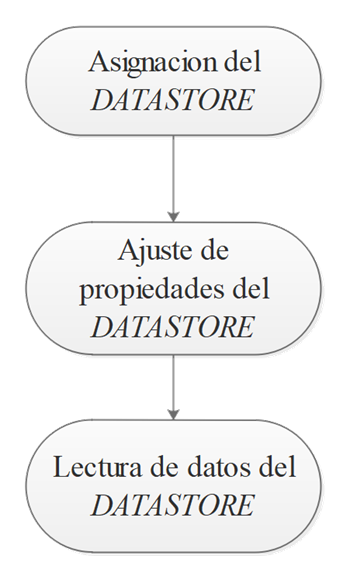

**Figura 2.-** Flujo de trabajo de un Datastore

La primer parte del pipeline del datastore incluye operaciones como:

- Detección de propiedades de los archivos del dataframe/modelo de datos

- Normalizacion de datos

%****
%En este ejercicio solo estaremos trabajando con un archivo
%contenido dentro del datastore
%****

%Se determina la direccion de los archivos que integran el "Datastore"
archivoCSV = [saveTempPath, newName];

%Visualización rápida de las primeras lineas del archivo de texto
%Como solo es un archivo se puede utilizar el comando dbtype
dbtype(archivoCSV,'10:15')

10    "male","group C","some high school","standard","none","80","75","73"
11    "female","group C","bachelor's degree","standard","completed","57","69","77"
12    "male","group B","some high school","standard","none","74","69","69"
13    "male","group B","master's degree","standard","none","53","50","49"
14    "male","group B","bachelor's degree","free/reduced","none","76","74","76"
15    "male","group A","some college","standard","none","70","73","70"



%Asignamos nuestro datastore dentro de MATLAB
dsGeneral = datastore(archivoCSV)

dsGeneral =   TabularTextDatastore with properties:

                      Files: {
                             ' ...\Maggie\Documents\MATLAB\TSISB_IA\tareaejercicio_1\temp\students.csv'
                             }
                    Folders: {
                             'C:\Users\Maggie\Documents\MATLAB\TSISB_IA\tareaejercicio_1\temp'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
         VariableNamingRule: 'modify'
          ReadVariableNames: true
              VariableNames: {'gender', 'race_ethnicity', 'parentalLevelOfEducation' ... and 5 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: ','
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFo

%Si tuvieramos muchos archivos, se utilizaria el siguiente comando
preview(dsGeneral) 

ans = 8×8 table
      gender      race_ethnicity    parentalLevelOfEducation         lunch          testPreparationCourse    mathScore    readingScore    writingScore
    __________    ______________    ________________________    ________________    _____________________    _________    ____________    ____________

    {'female'}     {'group D'}       {'some college'      }     {'standard'    }        {'completed'}         {'59'}         {'70'}          {'78'}   
    {'male'  }     {'group D'}       {'associate's degree'}     {'standard'    }        {'none'     }         {'96'}         {'93'}          {'87'}   
    {'female'}     {'group D'}       {'some college'      }     {'free/reduced'}        {'none'     }      


%Desde la version 2019, los nombres de las variables pueden incluir
%cualquier tipo de simbolos, ademas de no necesariamente comenzar solo
%con letras, por lo que matlab requiere el Flag "preserve" para considerar
%esta opción
dsGeneral.VariableNamingRule='preserve'

dsGeneral =   TabularTextDatastore with properties:

                      Files: {
                             ' ...\Maggie\Documents\MATLAB\TSISB_IA\tareaejercicio_1\temp\students.csv'
                             }
                    Folders: {
                             'C:\Users\Maggie\Documents\MATLAB\TSISB_IA\tareaejercicio_1\temp'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
         VariableNamingRule: 'preserve'
          ReadVariableNames: true
              VariableNames: {'gender', 'race_ethnicity', 'parentalLevelOfEducation' ... and 5 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: ','
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            Textscan


%Selección del delimitador de texto
dsGeneral.Delimiter=",";

%Modificacion de los nombres utilizados para cada caracteristica/feature
values=dsGeneral.VariableNames;
%Modificacion como si fuera un indexado de valores clásico
newValues=["hola", "esta", "es", "una", "prueba", "de", "cambio", "de etiquetas de columna"];
dsGeneral.VariableNames = newValues;
preview(dsGeneral)

ans = 8×8 table
       hola          esta                  es                    una              prueba          de      cambio    de etiquetas de columna
    __________    ___________    ______________________    ________________    _____________    ______    ______    _______________________

    {'female'}    {'group D'}    {'some college'      }    {'standard'    }    {'completed'}    {'59'}    {'70'}            {'78'}         
    {'male'  }    {'group D'}    {'associate's degree'}    {'standard'    }    {'none'     }    {'96'}    {'93'}            {'87'}         
    {'female'}    {'group D'}    {'some college'      }    {'free/reduced'}    {'none'     }    {'57'}    {'76'}            {'77'}         
    {'male'

## °°°Detección y modificación de propiedades de los datos contenidos en el archivo

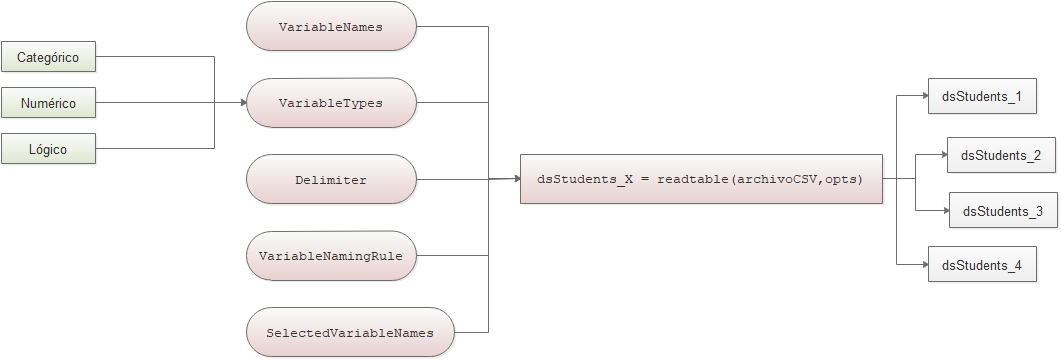

**Figura 3.- **Propiedades de un **datastore de tipo categorico-numérico**

%Visualizacion general de las opciones de importacion de los archivos
%dentro del datastore
opts = detectImportOptions(archivoCSV)

opts =   DelimitedTextImportOptions with properties:

   Format Properties:
                    Delimiter: {','}
                   Whitespace: '\b\t '
                   LineEnding: {'\n'  '\r'  '\r\n'}
                 CommentStyle: {}
    ConsecutiveDelimitersRule: 'split'
        LeadingDelimitersRule: 'keep'
       TrailingDelimitersRule: 'ignore'
                EmptyLineRule: 'skip'
                     Encoding: 'UTF-8'

   Replacement Properties:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'
             ExtraColumnsRule: 'addvars'

   Variable Import Properties: Set types by name using setvartype
                VariableNames: {'gender', 'race_ethnicity', 'parentalLevelOfEducation' ... and 5 more}
                VariableTypes: {'char', 'char', 'char' ... and 5 more}



%Visualizacion de los nombres y tipo de variables de las columnas
disp([opts.VariableNames' opts.VariableTypes'])

    {'gender'                  }    {'char'  }
    {'race_ethnicity'          }    {'char'  }
    {'parentalLevelOfEducation'}    {'char'  }
    {'lunch'                   }    {'char'  }
    {'testPreparationCourse'   }    {'char'  }
    {'mathScore'               }    {'double'}
    {'readingScore'            }    {'double'}
    {'writingScore'            }    {'double'}




%Modificacion del tipo de variables 
opts = setvaropts(opts,{'race_ethnicity','gender','parentalLevelOfEducation','lunch','testPreparationCourse'},'Type','categorical');
disp([opts.VariableNames' opts.VariableTypes'])

    {'gender'                  }    {'categorical'}
    {'race_ethnicity'          }    {'categorical'}
    {'parentalLevelOfEducation'}    {'categorical'}
    {'lunch'                   }    {'categorical'}
    {'testPreparationCourse'   }    {'categorical'}
    {'mathScore'               }    {'double'     }
    {'readingScore'            }    {'double'     }
    {'writingScore'            }    {'double'     }




%Desde la version 2019, los nombres de las variables pueden incluir
%cualquier tipo de simbolos, ademas de no necesariamente comenzar solo
%con letras, por lo que matlab requiere el Flag "preserve" para considerar
%esta opción
opts.VariableNamingRule='preserve';

%Selección del delimitador de texto
opts.Delimiter =',';

%Modificacion de los nombres utilizados para cada caracteristica/feature
%Asignacion a una variable particular
values=opts.VariableNames;
%Modificacion como si fuera un indexado de valores clásico
newValues={'hola', 'esta', 'es', 'una', 'prueba', 'de', 'cambio', 'de variables'};
opts.VariableNames = newValues;
dsStudents_1 = readtable(archivoCSV,opts);
head(dsStudents_1)

     hola      esta              es                una          prueba      de    cambio    de variables
    ______    _______    __________________    ____________    _________    __    ______    ____________

    female    group D    some college          standard        completed    59      70           78     
    male      group D    associate's degree    standard        none         96      93           87     
    female    group D    some college          free/reduced    none         57      76           77     
    male      group B    some college          free/reduced    none         70      70           63     
    female    group D    associate's degree    standard        none         83      85           

%regresamos los valores originales
opts.VariableNames = values;
dsStudents_2 = readtable(archivoCSV,opts);
head(dsStudents_2)

    gender    race_ethnicity    parentalLevelOfEducation       lunch        testPreparationCourse    mathScore    readingScore    writingScore
    ______    ______________    ________________________    ____________    _____________________    _________    ____________    ____________

    female       group D           some college             standard              completed             59             70              78     
    male         group D           associate's degree       standard              none                  96             93              87     
    female       group D           some college             free/reduced          none                  57             76              77     
    male    


%Podemos elegir con que caracteristicas queremos trabajar nuestra base de datos
opts.SelectedVariableNames = {'gender','mathScore','readingScore', 'writingScore'};
dsStudents_3 = readtable(archivoCSV,opts);
head(dsStudents_3)

    gender    mathScore    readingScore    writingScore
    ______    _________    ____________    ____________

    female       59             70              78     
    male         96             93              87     
    female       57             76              77     
    male         70             70              63     
    female       83             85              86     
    male         68             57              54     
    female       82             83              80     
    female       46             61              58     




%y crear distintos tipos de tablas a partir del datastore original
opts.SelectedVariableNames = {'race_ethnicity','mathScore','readingScore', 'writingScore'};
dsStudents_4 = readtable(archivoCSV,opts);
head(dsStudents_4)

    race_ethnicity    mathScore    readingScore    writingScore
    ______________    _________    ____________    ____________

       group D           59             70              78     
       group D           96             93              87     
       group D           57             76              77     
       group B           70             70              63     
       group D           83             85              86     
       group C           68             57              54     
       group E           82             83              80     
       group B           46             61              58     



## °°°Visualizaciones exploratorias de datos

En este momento se han creado 4 tablas que contienen los siguientes datos

- Tabla 1: No la usaremos

- Tabla 2: Todas las categorias de datos

- Tabla 3: Datos categóricos de genero y datos numéricos de las pruebas de matemáticas, lectura y escritura

- Tabla 4: Datos categóricos de raza etnica y datos numéricos de las pruebas de matemáticas, lectura y escritura

Vamos a realizar un análisis exploratorio de los datos, primero visualicemos un resumen de los datos categoricos contenidos en la tabla 2

### ### Resumen de datos categoricos

genero = categorical(dsStudents_2.gender);
grpCatGenero = categories(genero)

grpCatGenero = 2×1 cell array
    {'female'}
    {'male'  }


numCatGenero = countcats(genero)

numCatGenero =    492
   508


summary(genero)

     female      492 
     male        508 




etnia = categorical(dsStudents_2.race_ethnicity);
grpCatEtn = categories(etnia)

grpCatEtn = 5×1 cell array
    {'group A'}
    {'group B'}
    {'group C'}
    {'group D'}
    {'group E'}


numCatEtn = countcats(etnia)

numCatEtn =     79
   198
   323
   257
   143



%Vamos a reemplazar las categorias origniales por otros nombres
nuevasEtnias = {'Latino',...
                'Afroamericano',...
                'Americano',...
                'Asiatico',...
                'Europeo'};
nuevaEtnia = renamecats(etnia,nuevasEtnias);
summary(etnia)

     group A       79 
     group B      198 
     group C      323 
     group D      257 
     group E      143 


summary(nuevaEtnia)

     Latino              79 
     Afroamericano      198 
     Americano          323 
     Asiatico           257 
     Europeo            143 


## *** Ejercicio ***

Deberás mostrar cuantas categorias existen en:

- el nivel de educacion de los padres

- si contaron con un desayuno o no

- si hubo una preparacion previa a la prueba

%Categorías en "Nivel de educación de los padres"
niveledu = categorical(dsStudents_2.parentalLevelOfEducation);
grpCatNiv = categories(niveledu)

grpCatNiv = 6×1 cell array
    {'associate's degree'}
    {'bachelor's degree' }
    {'high school'       }
    {'master's degree'   }
    {'some college'      }
    {'some high school'  }


numCatNiv = countcats(niveledu)

numCatNiv =    204
   105
   215
    75
   224
   177



%Categorías en "Lunch"
desayuno = categorical(dsStudents_2.lunch);
grpCatDes = categories(desayuno)

grpCatDes = 2×1 cell array
    {'free/reduced'}
    {'standard'    }


numCatDes = countcats(desayuno)

numCatDes =    340
   660



%Categorías en "Preparación previa a la prueba"
preparacion = categorical(dsStudents_2.testPreparationCourse);
grpCatPrep = categories(preparacion)

grpCatPrep = 2×1 cell array
    {'completed'}
    {'none'     }


numCatPrep = countcats(preparacion)

numCatPrep =    344
   656


Además deberas de cambiar el nombre de las categorias en la columna "preparacion de la prueba" de la siguiente manera

- completed - > terminado

- none -> no terminado

%Reemplazo de los nombres de categorías dentro de "Preparación de la
%prueba"
nuevasTest = {'terminado',...
              'no terminado',...
             };
nuevaPrep = renamecats(preparacion,nuevasTest);
summary(preparacion)

     completed      344 
     none           656 


summary(nuevaPrep)

     terminado         344 
     no terminado      656 


### ### Resumen de datos numericos

Ahora vamos a realizar un resumen de los datos numéricos, lo cual puede incluir encontrar la media de los datos de pruebas numericas

#### ---Resumen general de una categoria

Los distintos tipos de operaciones numéricas que podemos realizar son las siguientes

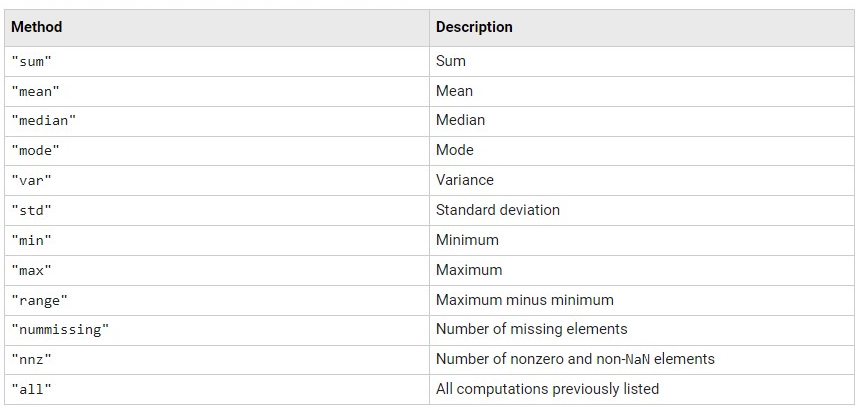

**Figura 4.-** Operaciones numéricas de una tabla

%Primero veremos el score promedio dependiendo del genero, utilizando la
%tabla 3
genderMean = groupsummary(dsStudents_3,"gender","mean") 

genderMean = 2×5 table
    gender    GroupCount    mean_mathScore    mean_readingScore    mean_writingScore
    ______    __________    ______________    _________________    _________________

    female       492            64.774             73.474               73.439      
    male         508             70.75             67.388               64.976      


%Podemos visualizar tambien el promedio dependiendo del grupo etnico
%utilizando la tabla 4
raceMean = groupsummary(dsStudents_4,"race_ethnicity","mean")

raceMean = 5×5 table
    race_ethnicity    GroupCount    mean_mathScore    mean_readingScore    mean_writingScore
    ______________    __________    ______________    _________________    _________________

       group A            79            65.696             69.203               67.848      
       group B           198            64.071              68.53               66.717      
       group C           323            65.511              68.61               66.805      
       group D           257            68.879              70.93               71.058      
       group E           143            77.427             76.615               75.035      


%Podemos realizar operaciones por conjuntos especificos por ejemplo de la
%siguiente manera
gen = dsStudents_2.gender;
race = dsStudents_2.race_ethnicity;
math = dsStudents_2.mathScore;
reading = dsStudents_2.readingScore;
writing = dsStudents_2.writingScore;
auxTable = table(gen,race,math, reading, writing)

auxTable = 1000×5 table
     gen       race      math    reading    writing
    ______    _______    ____    _______    _______

    female    group D     59       70         78   
    male      group D     96       93         87   
    female    group D     57       76         77   
    male      group B     70       70         63   
    female    group D     83       85         86   
    male      group C     68       57         54   
    female    group E     82       83         80   
    female    group B     46       61         58   
    male      group C     80       75         73   
    female    group C     57       69         77   
    male      group B     74       69         69   
    male      group B     53       50         49   
    male      group B     76       74         76   
    male      group A    

gender_raceMean = groupsummary(auxTable,["gen","race"],"mean")

gender_raceMean = 10×6 table
     gen       race      GroupCount    mean_math    mean_reading    mean_writing
    ______    _______    __________    _________    ____________    ____________

    female    group A        41         62.951         72.268          71.707   
    female    group B       112         62.268         72.384          71.893   
    female    group C       151          63.02         71.993          71.477   
    female    group D       118         63.839         72.873          74.161   
    female    group E        70         75.214         80.129          79.943   
    male      group A        38         68.658         65.895          63.684   
    male      group B        86         66.419         63.512          59.977   
    male      group C       172      

## *** Ejercicio ***

Realiza las siguientes operaciones 

- Cual es la media del grupo genero vs nivel de estudios de los padres

- Cual es el promedio de la raza etnica vs si se preparó o no para la prueba

- Cual es el promedio del genero vs si se preparó o no para la prueba

%Media del genero vs. nivel de estudios de los padres
genero = dsStudents_2.gender;
nivel = dsStudents_2.parentalLevelOfEducation;
auxTable = table(genero,nivel)

auxTable = 1000×2 table
    genero          nivel       
    ______    __________________

    female    some college      
    male      associate's degree
    female    some college      
    male      some college      
    female    associate's degree
    male      some high school  
    female    associate's degree
    female    some high school  
    male      some high school  
    female    bachelor's degree 
    male      some high school  
    male      master's degree   
    male      bachelor's degree 
    male      some college      
    male      master's degree   
    male      master's degree   


gender_levelMean = groupsummary(auxTable,["genero","nivel"],"mean")

gender_levelMean = 12×3 table
    genero          nivel           GroupCount
    ______    __________________    __________

    female    associate's degree       101    
    female    bachelor's degree         52    
    female    high school              116    
    female    master's degree           33    
    female    some college             106    
    female    some high school          84    
    male      associate's degree       103    
    male      bachelor's degree         53    
    male      high school               99    
    male      master's degree           42    
    male      some college             118    
    male      some high school          93    


%Promedio de la raza etnica vs. si se preparó o no para la prueba
raza = dsStudents_2.race_ethnicity;
prueba = dsStudents_2.testPreparationCourse;
auxTable = table(raza,prueba)

auxTable = 1000×2 table
     raza       prueba  
    _______    _________

    group D    completed
    group D    none     
    group D    none     
    group B    none     
    group D    none     
    group C    none     
    group E    none     
    group B    none     
    group C    none     
    group C    completed
    group B    none     
    group B    none     
    group B    none     
    group A    none     
    group C    none     
    group E    none     


race_testMean = groupsummary(auxTable,["raza","prueba"],"mean")

race_testMean = 10×3 table
     raza       prueba      GroupCount
    _______    _________    __________

    group A    completed        31    
    group A    none             48    
    group B    completed        66    
    group B    none            132    
    group C    completed       101    
    group C    none            222    
    group D    completed        97    
    group D    none            160    
    group E    completed        49    
    group E    none             94    



%Promedio del genero vs. si se preparó o no para la prueba
genero = dsStudents_2.gender;
prueba = dsStudents_2.testPreparationCourse;
auxTable = table(genero,prueba)

auxTable = 1000×2 table
    genero     prueba  
    ______    _________

    female    completed
    male      none     
    female    none     
    male      none     
    female    none     
    male      none     
    female    none     
    female    none     
    male      none     
    female    completed
    male      none     
    male      none     
    male      none     
    male      none     
    male      none     
    male      none     


gender_testMean = groupsummary(auxTable,["genero","prueba"],"mean")

gender_testMean = 4×3 table
    genero     prueba      GroupCount
    ______    _________    __________

    female    completed       177    
    female    none            315    
    male      completed       167    
    male      none            341    


### ### Modificación de las columnas en modelos de datos

Podemos realizar ligeras modificaciones a las columnas (caracteristicas de nuestro modelo de datos) realizando las siguientes operaciones

- Crear tablas a partir de datos específicos

- Agregar una columna de datos

- Mover columnas de datos

- Remover columnas de datos

%Creacion de tablas a partir de datos originales
auxTable_1 = table(gen, math, reading);
head(auxTable_1)

     gen      math    reading
    ______    ____    _______

    female     59       70   
    male       96       93   
    female     57       76   
    male       70       70   
    female     83       85   
    male       68       57   
    female     82       83   
    female     46       61   



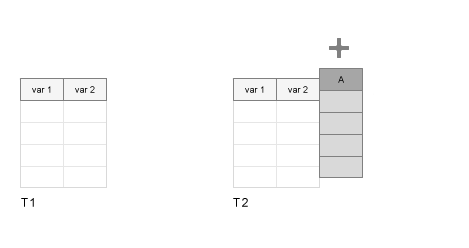

**Figura 5.- **Agregado de caracteristicas de un modelo de datos

%Agregado de valores a tablas ya existentes
auxTable2 = addvars(auxTable_1,writing);
head(auxTable2)

     gen      math    reading    writing
    ______    ____    _______    _______

    female     59       70         78   
    male       96       93         87   
    female     57       76         77   
    male       70       70         63   
    female     83       85         86   
    male       68       57         54   
    female     82       83         80   
    female     46       61         58   



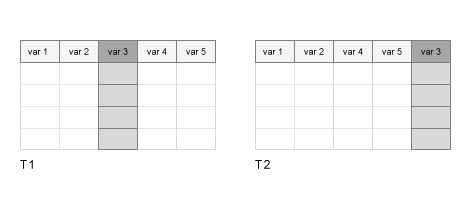

**Figura 6.- **Reordenamiento de caracteristicas de un modelo de datos

%Reordenamiento de caracteristicas de la tabla
auxTable_3 = movevars(auxTable2,'reading','after','writing');
head(auxTable_3)

     gen      math    writing    reading
    ______    ____    _______    _______

    female     59       78         70   
    male       96       87         93   
    female     57       77         76   
    male       70       63         70   
    female     83       86         85   
    male       68       54         57   
    female     82       80         83   
    female     46       58         61   



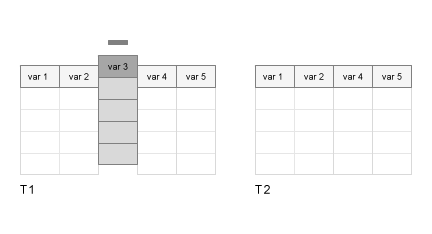

**Figura 7.- **Eliminacion de caracteristicas de un modelo de datos

%Eliminacion de caracteristicas de la tabla
auxTable_4 = removevars(auxTable2,{'reading'});
head(auxTable_4)

     gen      math    writing
    ______    ____    _______

    female     59       78   
    male       96       87   
    female     57       77   
    male       70       63   
    female     83       86   
    male       68       54   
    female     82       80   
    female     46       58   



### ###Filtrado de informacion basado en reglas de valores

%Podemos tambien filtrar los datos por grupos de informacion
%filtrado de la informacion de la tabla auxTable_2 para resultados de datos
%de prueba Matemáticas mayores a 60 pero menores a 80
auxTable = table(gen,math,reading,writing);
head(auxTable)

     gen      math    reading    writing
    ______    ____    _______    _______

    female     59       70         78   
    male       96       93         87   
    female     57       76         77   
    male       70       70         63   
    female     83       85         86   
    male       68       57         54   
    female     82       83         80   
    female     46       61         58   




promBetween_60_80 = groupfilter(auxTable,"math",@(x) min(x) >= 60 && max(x) <= 80,"math");
head(promBetween_60_80)

     gen      math    reading    writing
    ______    ____    _______    _______

    male       70       70         63   
    male       68       57         54   
    male       80       75         73   
    male       74       69         69   
    male       76       74         76   
    male       70       73         70   
    female     80       82         85   
    female     65       71         74   



auxMean_Table = groupsummary(promBetween_60_80,"gen","max")

auxMean_Table = 2×5 table
     gen      GroupCount    max_math    max_reading    max_writing
    ______    __________    ________    ___________    ___________

    female       243           80           97             99     
    male         245           80           88             87     


## *** Ejercicio ***

Realiza las siguientes operaciones 

- Crea una tabla que contenga las siguientes categorias en este orden: Preparacion de la prueba, genero, Resultado de matemáticas, Resultado de lectura, Resultado de escritura

- Calcula el promedio de los tres valores de las pruebas y coloca el valor al final de las columnas

- Agrupa los resultados por promedio y clasificalos para valores mayores o iguales a 60 pero menores o iguales a 80. ¿Cuantos datos quedaron en total?

- Cual es el promedio general del género masculino que si se preparo para la prueba

- Cual es el promedio general del género femenino que no se preparo para la prueba

- De acuerdo con los datos, ¿Existe una relación directa entre prepararse para la prueba y no prepararse para la prueba?

% 1. Crea una tabla que contenga las siguientes categorias en este orden: Preparacion de la prueba, genero, Resultado de matemáticas, Resultado de lectura, Resultado de escritura
PreparacionPrueba = dsStudents_2.testPreparationCourse

PreparacionPrueba = 1000×1 categorical array
     completed 
     none 
     none 
     none 
     none 
     none 
     none 
     none 
     none 
     completed 
     none 
     none 
     none 
     none 
     none 
     none 
     none 
     none 
     none 
     completed 
     none 
     completed 
     none 
     none 
     completed 
     none 
     none 
     none 
     none 
     none 


Genero = dsStudents_2.gender;
ResultadoMatematicas = dsStudents_2.mathScore;
ResultadoLectura = dsStudents_2.readingScore;
ResultadoEscritura = dsStudents_2.writingScore;
auxTable1 = table(PreparacionPrueba,Genero,ResultadoMatematicas,ResultadoLectura,ResultadoEscritura);
head(auxTable1)

    PreparacionPrueba    Genero    ResultadoMatematicas    ResultadoLectura    ResultadoEscritura
    _________________    ______    ____________________    ________________    __________________

        completed        female             59                    70                   78        
        none             male               96                    93                   87        
        none             female             57                    76                   77        
        none             male               70                    70                   63        
        none             female             83                    85                   86        
        none             male               68                    57                   54        
        none             female             8

% 2. Calcula el promedio de los tres valores de las pruebas y coloca el valor al final de las columnas
promedio = mean([auxTable1.ResultadoMatematicas, auxTable1.ResultadoLectura, auxTable1.ResultadoEscritura],2);
auxTable2= addvars(auxTable1,promedio);
head(auxTable2)

    PreparacionPrueba    Genero    ResultadoMatematicas    ResultadoLectura    ResultadoEscritura    promedio
    _________________    ______    ____________________    ________________    __________________    ________

        completed        female             59                    70                   78                 69 
        none             male               96                    93                   87                 92 
        none             female             57                    76                   77                 70 
        none             male               70                    70                   63             67.667 
        none             female             83                    85                   86             84.667 
        none             

% 3. Agrupa los resultados por promedio y clasificalos para valores mayores o iguales a 60 pero menores o iguales a 80. ¿Cuantos datos quedaron en total?
testsBetween_60_80 = groupfilter(auxTable2,["ResultadoMatematicas","ResultadoLectura","ResultadoEscritura","promedio"],@(x) min(x) >= 60 && max(x) <= 80,["ResultadoMatematicas","ResultadoLectura","ResultadoEscritura","promedio"]);
head(testsBetween_60_80)

    PreparacionPrueba    Genero    ResultadoMatematicas    ResultadoLectura    ResultadoEscritura    promedio
    _________________    ______    ____________________    ________________    __________________    ________

        none             male               70                    70                   63             67.667 
        none             male               80                    75                   73                 76 
        none             male               74                    69                   69             70.667 
        none             male               76                    74                   76             75.333 
        none             male               70                    73                   70                 71 
        completed        

auxMean_Table = groupsummary(testsBetween_60_80,["ResultadoMatematicas","ResultadoLectura","ResultadoEscritura","promedio"])

auxMean_Table = 300×5 table
    ResultadoMatematicas    ResultadoLectura    ResultadoEscritura    promedio    GroupCount
    ____________________    ________________    __________________    ________    __________

             60                    65                   67                 64         1     
             60                    66                   64             63.333         1     
             60                    67                   61             62.667         1     
             60                    67                   74                 67         1     
             60                    69                   70             66.333         1     
             60                    73                   68                 67         1     
             60                    74                   6

Después de filtar la información según lo establecido, quedaron 300 datos.

% 4. Cual es el promedio general del género masculino que si se preparo para la prueba
promedio_masculino_preparado = mean(testsBetween_60_80(testsBetween_60_80.('Genero') == 'male' & testsBetween_60_80.('PreparacionPrueba') == 'completed', :).('promedio'));
% 5. Cual es el promedio general del género femenino que no se preparo para la prueba
promedio_femenino_no_preparado = mean(testsBetween_60_80(testsBetween_60_80.('Genero') == 'female' & testsBetween_60_80.('PreparacionPrueba') == 'none', :).('promedio'));
% 6. De acuerdo con los datos, ¿Existe una relación directa entre prepararse para la prueba y no prepararse para la prueba?
num_datos_60_80 = height(testsBetween_60_80);
disp(['Total de datos con promedio entre 60 y 80: ' num2str(num_datos_60_80)]);

Total de datos con promedio entre 60 y 80: 303


disp(['Promedio general masculino preparado: ' num2str(promedio_masculino_preparado)]);

Promedio general masculino preparado: 70.3838


disp(['Promedio general femenino no preparado: ' num2str(promedio_femenino_no_preparado)]);

Promedio general femenino no preparado: 70.3129


% Según los datos, no hay una relación directa entre prepararse para la
% prueba y no hacerlo porque la variación es de centésimas.

**NOTA IMPORTANTE:**

Utilicé códigos hechos por ChatGPT. 

Ingresé todas las instrucciones del ejercicio al chat pero sólo utilicé los códigos a partir del punto 4; para lograr obtener el punto 3 di una instrucción específica: *como sacar el promedio de tres columnas y visualizarlo en una tabla; *de esta manera pude obtener el promedio directamente en una tabla y no en una subtabla o que tuviera datos categóricos; el código lo modifique a mi beneficio para que MATLAB pudiera correr el código sin problemas.

### ### Discretizacion de datos en categorias

%Vamos a establecer los siguientes valores de calificaciones en el formato
%americano de calificaciones donde
%Valor | calificacion
%0 59  | F
%60 69 | D
%70 79 | C
%80 89 | B
%90 99 | A
%100   | A+

%Primero estableceremos nuestras nuevas categorias de datos
%etiquetas
calAme = {'F', 'D', 'C', 'B', 'A', 'A+'};

%Limites de calificaciones
limit = [0 59 69 79 89 99 100];
auxVal = dsStudents_3.mathScore; %Solo para guardar el valor
dsStudents_3.mathScore = discretize(dsStudents_3.mathScore, limit, 'categorical', calAme);
summary(dsStudents_3.mathScore)

     F       256 
     D       256 
     C       219 
     B       186 
     A        70 
     A+       13 


head(dsStudents_3)

    gender    mathScore    readingScore    writingScore
    ______    _________    ____________    ____________

    female        D             70              78     
    male          A             93              87     
    female        F             76              77     
    male          C             70              63     
    female        B             85              86     
    male          D             57              54     
    female        B             83              80     
    female        F             61              58     



dsStudents_3.mathScore = auxVal; %Regreso el valor original para no entorpecer la BD
head(dsStudents_3)

    gender    mathScore    readingScore    writingScore
    ______    _________    ____________    ____________

    female       59             70              78     
    male         96             93              87     
    female       57             76              77     
    male         70             70              63     
    female       83             85              86     
    male         68             57              54     
    female       82             83              80     
    female       46             61              58     

